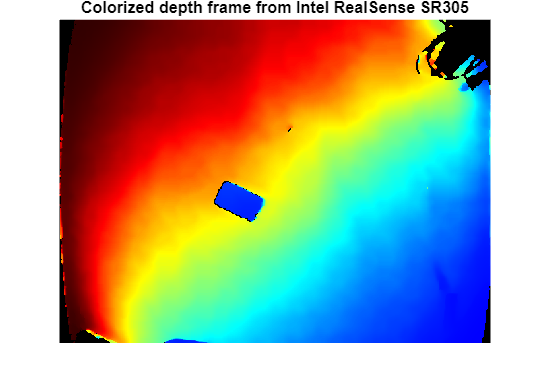

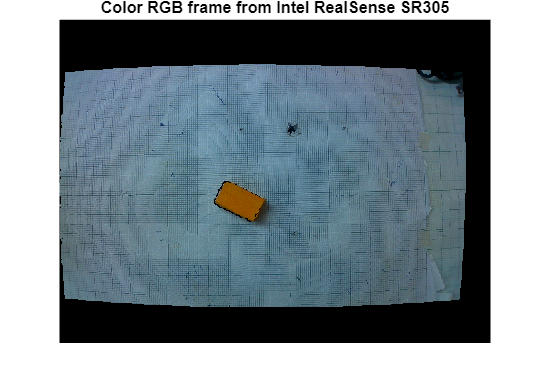

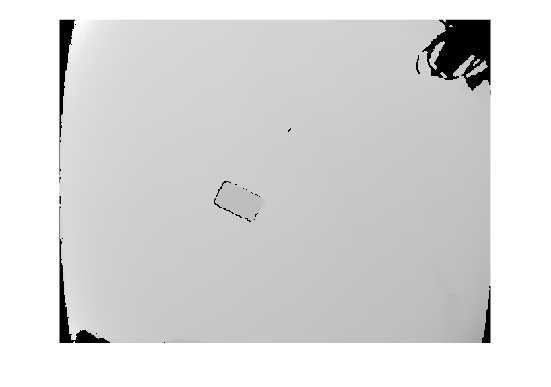

depth_img =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.5048    0.5052    0.5056    0.5059    0.5062    0.5063    0.5062    0.5061    0.5013    0.4977    0.4968    0.4962    0.4957    0.4952    0.4947    0.4933    0.4892    0.4852    0.4849    0.4847    0.4844    0.4804    0.4803    0.4763    0.4762    0.4722    0.4719
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4998    0.5052    0.5056    0.5059    0.5062    0.5062    0.5061    0.5061    0.5008    0.4979    0.4972    0.4964    0.4961    0.4954    0.4949    0.4927    0.4892    0.4852    0.4849    0.4847    0.4844    0.4803    0.4802    0.4761    0.4761    0.4

rgb_img = 480×640×3 uint8 array
rgb_img(:,:,1) =

     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0  

depth_data =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.5048    0.5052    0.5056    0.5059    0.5062    0.5063    0.5062    0.5061    0.5013    0.4977    0.4968    0.4962    0.4957    0.4952    0.4947    0.4933    0.4892    0.4852    0.4849    0.4847    0.4844    0.4804    0.4803    0.4763    0.4762    0.4722    0.4719


[depth_img, rgb_img, depth_data] = depth_example()

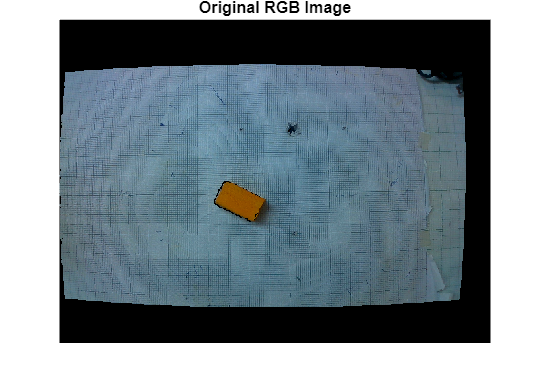



%% 1. Read Image
imgRGB = rgb_img; % Pulling the source image
figure; imshow(imgRGB);
title('Original RGB Image');

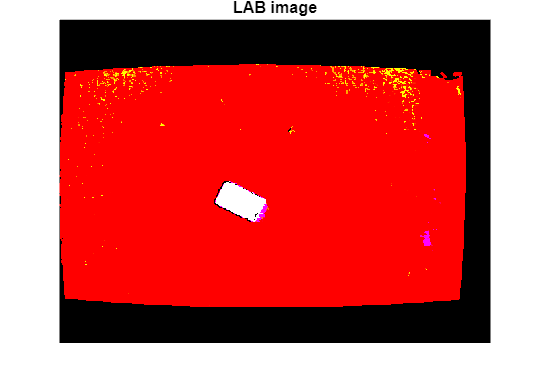

%% 2. Convert to LAB
imgLab = rgb2lab(imgRGB); % Switch to LAB space to make color separation easier
[L,a,b] = imsplit(imgLab); % Break it down into lightness and color channels
imshow(imgLab)
title ('LAB image');

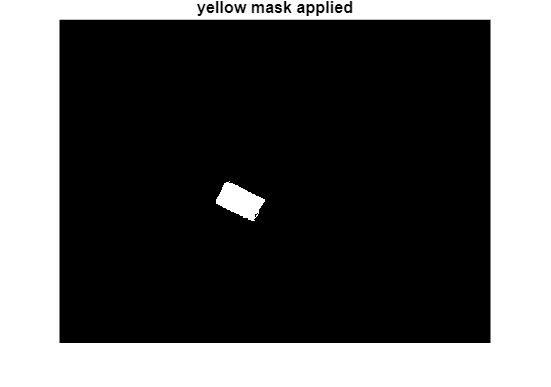

%% 3. Segment Yellow Block
yellowMask = b > 25; % Isolating yellow using the 'b' channel (blue-yellow)
yellowMask = bwareaopen(yellowMask, 200); % Getting rid of small noise or "speckles"
imshow(yellowMask)
title ('yellow mask applied');

%% 4. Extract Properties
% Use regionprops to find where the block is and how it's sitting
yellowStats = regionprops(yellowMask, ...
 'BoundingBox','Centroid','Area','Orientation', 'MajorAxisLength','MinorAxisLength')

yellowStats = struct with fields:
               Area: 2415
           Centroid: [268.5710 270.0451]
        BoundingBox: [232.5000 240.5000 73 59]
    MajorAxisLength: 73.8500
    MinorAxisLength: 43.4433
        Orientation: -24.6498



%% 5. Making a box around the block with the right orientation
theta = -deg2rad(yellowStats.Orientation) % Flipping the angle to radians for math

theta = 0.4302

cx = yellowStats.Centroid(1) % Center point X

cx = 268.5710

cy = yellowStats.Centroid(2) % Center point Y

cy = 270.0451

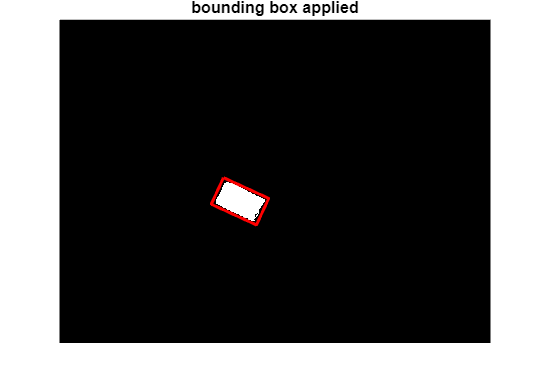

L = yellowStats.MajorAxisLength / 2; % Half-length
W = yellowStats.MinorAxisLength / 2; % Half-width
% Setting up the corners of a rectangle centered at (0,0) before we rotate it
corners = [ -L -W;
 L -W;
 L W;
 -L W]';

% Standard 2D rotation matrix
R = [cos(theta) -sin(theta);
 sin(theta) cos(theta)];
rotated = R * corners; % Spin the corners by our angle
% Move the rotated box back onto the actual block position
x = rotated(1,:) + cx;
y = rotated(2,:) + cy;
imshow(yellowMask)
title('bounding box applied');
hold on
 plot([x x(1)], [y y(1)], 'r', 'LineWidth', 2)
hold off

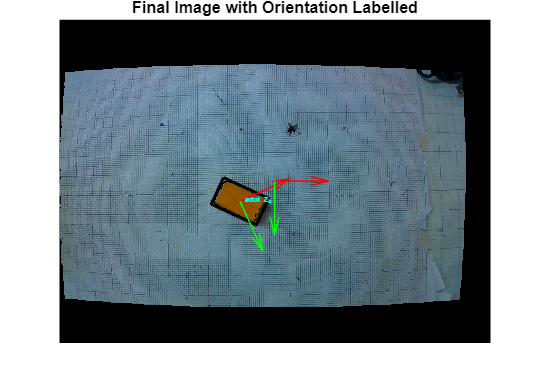

% 6. putting everything down on the final image
imshow(imgRGB)
title ('Final Image with Orientation Labelled')
hold on
% Draw the box and local axes on the yellow block
 plot([x x(1)], [y y(1)], 'k', 'LineWidth', 2)
 axisLength = 80;

 % Defining local X and Y axes for the block


 x_axis = axisLength * [cos(theta); -sin(theta)];
 y_axis = axisLength * [sin(theta); cos(theta)];

 quiver(cx, cy, x_axis(1), x_axis(2), ...
 0, 'r','LineWidth',1,'MaxHeadSize',1); % Draw X-axis in Red
 quiver(cx, cy, y_axis(1), y_axis(2), ...
 0, 'g','LineWidth',1,'MaxHeadSize',1); % Draw Y-axis in Green

 % Visual cue for the Z-axis pointing up at the camera
 text(cx, cy, ' \odot Z_b', ...
 'Color','c','FontSize',5,'FontWeight','bold');


 % Now, let's mark the Camera Frame (center of the image)
 [rows, cols, ~] = size(imgRGB);
 center_x = cols / 2;
 center_y = rows / 2;
 theta_c = 0;

 theta_c = deg2rad(theta_c);
 R_mat = [cos(theta_c) -sin(theta_c);
 sin(theta_c) cos(theta_c)];

 x_axis_c = [axisLength; 0];
 y_axis_c = [0; axisLength];

 x_rot = R_mat * x_axis_c;
 y_rot = R_mat * y_axis_c;
 quiver(center_x, center_y, x_rot(1), x_rot(2), ...
 0, 'r','LineWidth',1,'MaxHeadSize',1); % Camera X

 quiver(center_x, center_y, y_rot(1), y_rot(2), ...
 0, 'g','LineWidth',1,'MaxHeadSize',1); % Camera Y
 plot(center_x, center_y, 'g', 'MarkerSize', 8, 'LineWidth', 2)
hold off

%% 7. 3D Transformation (Camera to Block)
% Physical dimensions in cm finding depth

height = []  % Preallocate


height =

     []



maskedDepth = depth_img .* yellowMask;  % Multiply mask
[rows, cols] = size(maskedDepth);
k=1;
for i = 1:rows
    for j = 1:cols
        if maskedDepth(i,j) > 0
            height(k) = maskedDepth(i,j);
            k= k+1;
        end
    end
end
avg_block_z = median(height) * 100

avg_block_z = 37.6710


%heightCamera = 53.5;
depthToBlock = avg_block_z; % This is the Z distance from the camera lens to the block top
% Calibration: How many centimeters is one pixel?
% this needs to be fixed
pixelToCm = 0.1;
% Figure out the translation (how far the block is from the center)
% tx and ty convert the pixel offset into real-world centimeters
tx = (cx - center_x) * pixelToCm;
ty = (cy - center_y) * pixelToCm;
tz = depthToBlock;
% Create the 3D rotation matrix for the block around the Z-axis
R_cb = [ cos(theta) -sin(theta) 0;
 sin(theta) cos(theta) 0;
 0 0 1];
% Combine rotation and translation into one 4x4 Transformation Matrix
T_c_b = [ R_cb, [tx; ty; tz];
 0, 0, 0, 1 ];
% Print the results to the command window
fprintf('\n--- Transformation Matrix (Camera to Block) ---\n');


--- Transformation Matrix (Camera to Block) ---


disp(T_c_b);

    0.9089   -0.4171         0   -5.1429
    0.4171    0.9089         0    3.0045
         0         0    1.0000   37.6710
         0         0         0    1.0000



fprintf('Block position relative to Camera (cm):\n');

Block position relative to Camera (cm):


fprintf('X: %.2f, Y: %.2f, Z: %.2f\n', tx, ty, tz);

X: -5.14, Y: 3.00, Z: 37.67


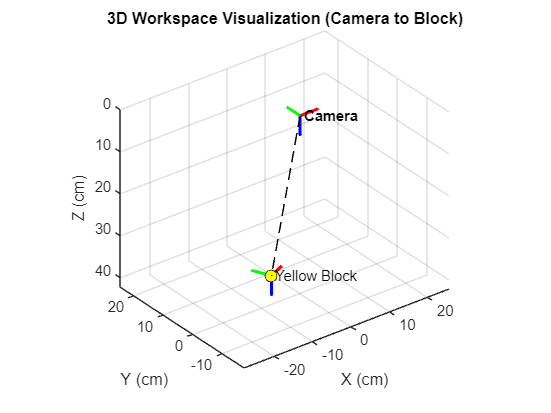

%% 8. 3D Visualization
figure;
hold on; grid on; axis equal;
xlabel('X (cm)'); ylabel('Y (cm)'); zlabel('Z (cm)');
title('3D Workspace Visualization (Camera to Block)');
% Setup the camera frame at the origin (0,0,0)
% We reverse Z-direction so "down" looks correct in the 3D plot
set(gca, 'ZDir', 'reverse');
quiver3(0,0,0, 5, 0, 0, 'r', 'LineWidth', 2); % Camera X
quiver3(0,0,0, 0, 5, 0, 'g', 'LineWidth', 2); % Camera Y
quiver3(0,0,0, 0, 0, 5, 'b', 'LineWidth', 2); % Camera Z
text(0,0,0, ' Camera', 'FontSize', 10, 'FontWeight', 'bold');
% Plot the block's frame using the values from our T_c_b matrix
bx = T_c_b(1,4);
by = T_c_b(2,4);
bz = T_c_b(3,4);
% Pull the rotated directions for the block's X, Y, and Z axes
ux = T_c_b(1:3, 1) * 5;
uy = T_c_b(1:3, 2) * 5;
uz = T_c_b(1:3, 3) * 5;
quiver3(bx, by, bz, ux(1), ux(2), ux(3), 'r', 'LineWidth', 2); % Block X
quiver3(bx, by, bz, uy(1), uy(2), uy(3), 'g', 'LineWidth', 2); % Block Y
quiver3(bx, by, bz, uz(1), uz(2), uz(3), 'b', 'LineWidth', 2); % Block Z
plot3(bx, by, bz, 'ko', 'MarkerFaceColor', 'y', 'MarkerSize', 8);
text(bx, by, bz, ' Yellow Block', 'FontSize', 10);
% Draw a dashed line from the camera to the block to show the path
plot3([0 bx], [0 by], [0 bz], 'k--');
view(3); % Tilt the view so we can see the 3D depth
hold off;